load("..\data\imgV2.mat");
perfCm = buildcmap('yrk');
barCm = buildcmap('bwr');

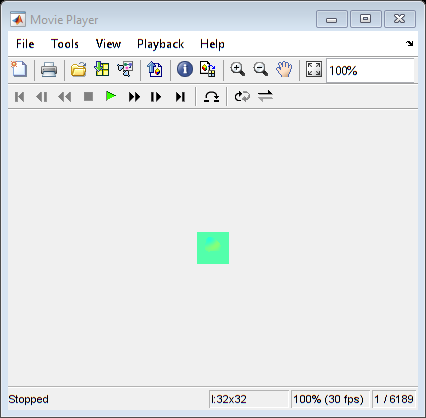

% Organize the data into "snapshots": spatial is rows, time is columns
stdMap = std(imgV2,[],3);
imgV2Filt = imgV2 .* repmat(stdMap > max(stdMap(:)) * 0.5, 1, 1, size(imgV2, 3));
flatV = reshape(imgV2Filt(:,:,1000:1500),32*32,[]);
X = flatV(:,1:end-2);
Y = flatV(:,2:end-1);

% Select heart and lung pixels
heartPix = [7,15];
lungPix = [14,22];

% Preview of what the real data looks like
playVideo(imgV2Filt);

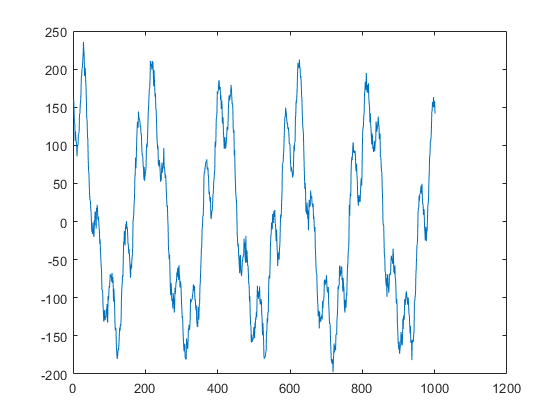


sig = imgV2(:,:,1000:2000);
figure; plot(squeeze(sig(heartPix(1),heartPix(2),:)));

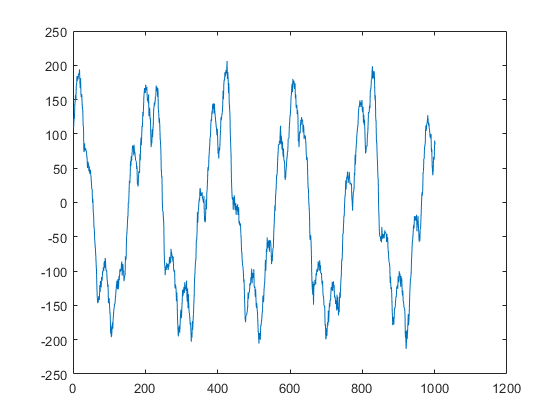

figure; plot(squeeze(sig(lungPix(1),lungPix(2),:)));

% Initialize DMD class and properties
m = 128; % number of samples to take into consideration
projType = 2;

dmd = DMD();
rank = 20; % number of singular values to keep
tSize = size(X, 2); % number of time samples
fs = 50; % sampling frequency of signal (for the continuous reconstruction)

% Try with compressed sensing
[cX, cY, C] = compressData(dmd, X, Y, m, projType);

% Test online DMD
w = 0.9;
weight = repmat(sqrt(w) .^ ((size(cX, 2) - 1) : -1 : 0), size(cX, 1), 1);
cutoff = 128; %find(weight(1,:) >= 0.1, 1);

cX = cX .* weight;
cY = cY .* weight;

% For #states >> #snapshots
tic
Atilde = cY * pinv(cX);
P = inv(cX * cX');

toc

Elapsed time is 0.142806 seconds.


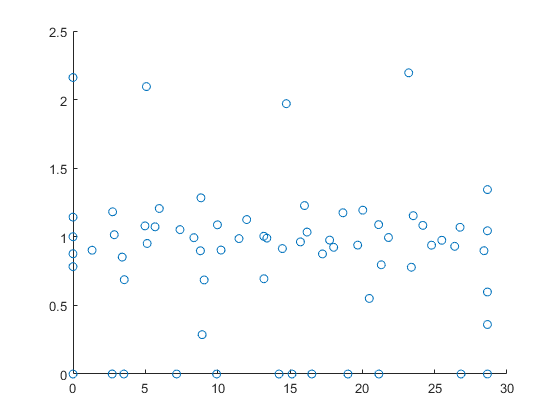


[W,D] = eig(Atilde);
lambda = diag(D);

uniqueIdx = (imag(lambda) >= 0);
lambda = lambda(uniqueIdx);

freqs = 180 * angle(lambda)/(2 * pi ^ 2);
mags = abs(lambda);
figure; scatter(freqs,mags);

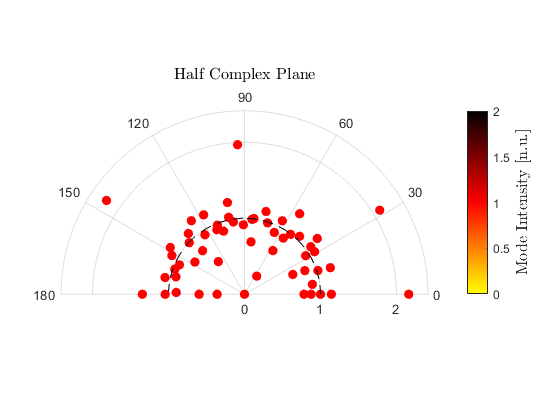

nyqPlot(dmd, ones(size(freqs)), freqs, mags, lambda);


Xnext = flatV(:,end-1);
Ynext = flatV(:,end);

[cXnext, cYnext, C] = compressData(dmd, Xnext, Ynext, m, projType);

tic
[Anext, Pnext] = updateKoopman(dmd, Atilde, P, cXnext, cYnext, w);
toc

Elapsed time is 0.023028 seconds.



[W,D] = eig(Anext);
lambda = diag(D);
omega = log(lambda)/(1/fs);

% PROBLEM: ONLINE DMD DOESN'T ALLOW CACLULATION OF B

Xnew = flatV(:,cutoff - 1:end - 1);
Ynew = flatV(:,cutoff:end);

[Xnew, Ynew, C] = compressData(dmd, Xnew, Ynew, m, projType);

rank = 128;
[U,S,V] = svd(Xnew,'econ');
Ur = U(:,1:rank);
Sr = S(1:rank,1:rank);
Vr = V(:,1:rank);

tmp = Ynew * Vr / Sr;

fSize = size(Xnew, 1);
for i = 1:rank
    Phi(:,i) = 1/lambda(i) * tmp * W(:,i); % paper isn't clear on how to calculate Phi
end

Unable to perform assignment because the size of the left side is 1024-by-1 and the size of the right side is 128-by-1.

b = inv(D) / Phi * Xnew(:,2);

[lambda, omega, Phi, b, ~] = cleanModes(dmd, lambda, omega, Phi, b);
[norms, mags, freqs] = interpModes(dmd, lambda, Phi, b);

% uniqueIdx = (imag(lambda) >= 0);
% lambda = lambda(uniqueIdx);
% 
% freqs = 180 * angle(lambda)/(2 * pi ^ 2);
% mags = abs(lambda);
% figure; scatter(freqs,mags);
% 
% nyqPlot(dmd, ones(size(freqs)), freqs, mags, lambda);

% Visualization
damFreq(dmd, norms, mags, freqs);
domStruct(dmd, freqs, lambda, Phi, b, tSize);
nyqPlot(dmd, norms, freqs, mags, lambda);
powSpect(dmd, Xnew, freqs, norms, fs);
[Xcomps, Xtotal] = reconData(dmd, lambda, omega, Phi, b, tSize, fs, 'cont');

playVideo(reshape(real(Xtotal),32,32,[]));

sig = real(reshape(Xtotal,32,32,tSize));
figure; plot(squeeze(sig(heartPix(1),heartPix(2),:)));
figure; plot(squeeze(sig(lungPix(1),lungPix(2),:)));

% Initialize DMD class and properties
dmd = DMD();
rank = 20;
tSize = size(X, 2);
fs = 50;

% Modified Exact DMD
tic
[Ur, Sr, Vr, Atilde] = fitKoopman(dmd, X, Y, rank, tSize);
[lambda, omega, Phi, b] = fitModes(dmd, Ur, Sr, Vr, Atilde, X, Y, fs, 'exact-mod');
[lambda, omega, Phi, b, ~] = cleanModes(dmd, lambda, omega, Phi, b);
[norms, mags, freqs] = interpModes(dmd, lambda, Phi, b);
toc

Elapsed time is 0.049702 seconds.


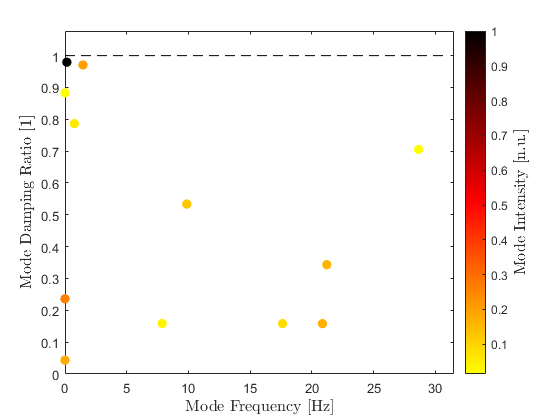


% Visualization
damFreq(dmd, norms, mags, freqs);

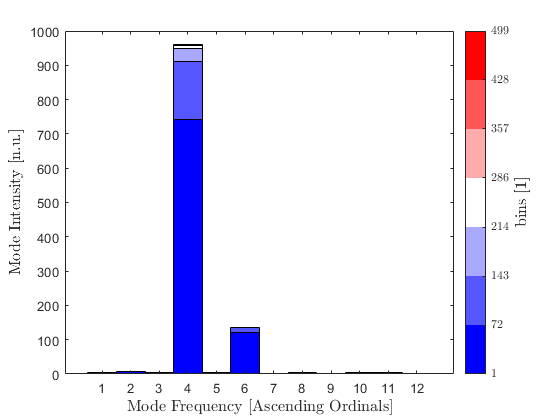

domStruct(dmd, freqs, lambda, Phi, b, tSize);

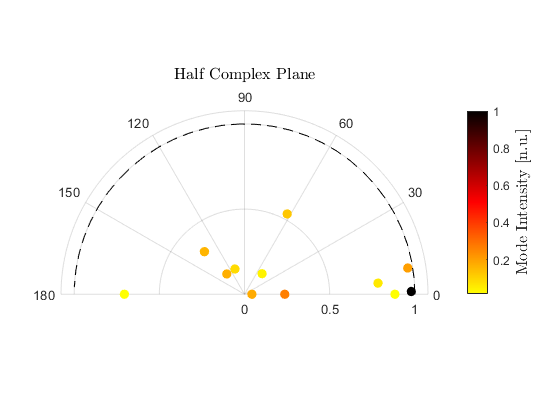

nyqPlot(dmd, norms, freqs, mags, lambda);

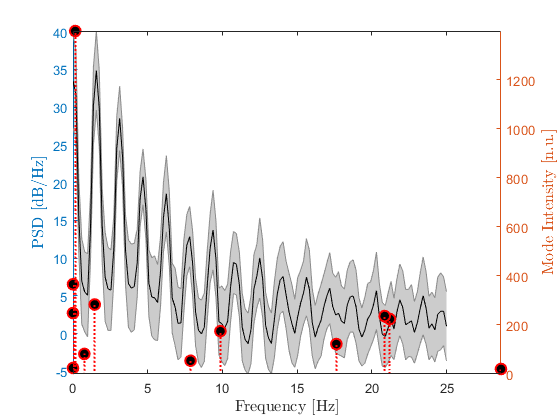

powSpect(dmd, X, freqs, norms, fs);

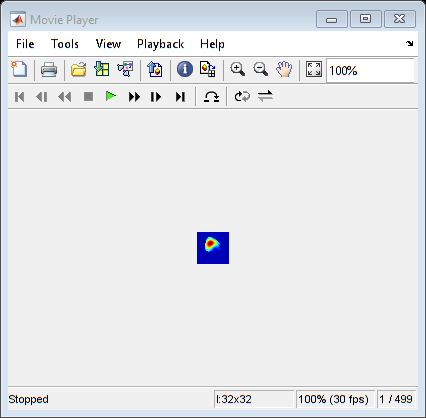

[Xcomps, Xtotal] = reconData(dmd, lambda, omega, Phi, b, tSize, fs, 'cont');

playVideo(reshape(real(Xtotal),32,32,[]));

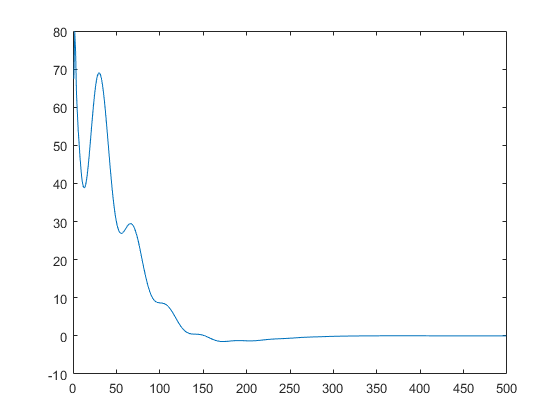


sig = real(reshape(Xtotal,32,32,tSize));
figure; plot(squeeze(sig(heartPix(1),heartPix(2),:)));

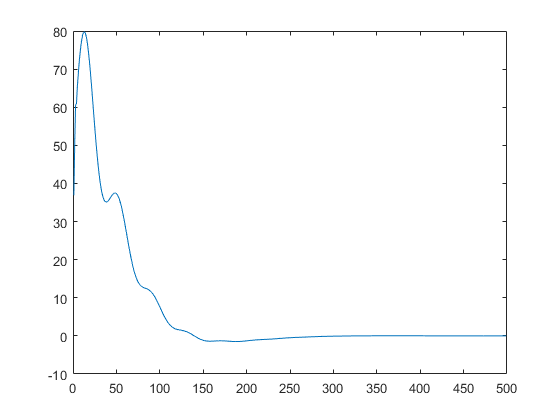

figure; plot(squeeze(sig(lungPix(1),lungPix(2),:)));

% Compressed Modified Exact DMD
m = 128;
projType = 2;

tic
[cX, cY, C] = compressData(dmd, X, Y, m, projType);
[Ur, Sr, Vr, Atilde] = fitKoopman(dmd, cX, cY, rank, tSize);
[lambda, omega, Phi, b] = fitModes(dmd, Ur, Sr, Vr, Atilde, cX, cY, fs, 'exact-mod', X, Y);
[lambda, omega, Phi, b, ~] = cleanModes(dmd, lambda, omega, Phi, b);
[norms, mags, freqs] = interpModes(dmd, lambda, Phi, b);
toc

Elapsed time is 0.051180 seconds.


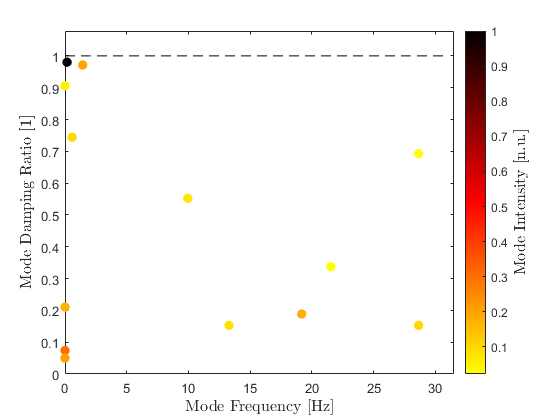


% Visualization
damFreq(dmd, norms, mags, freqs);

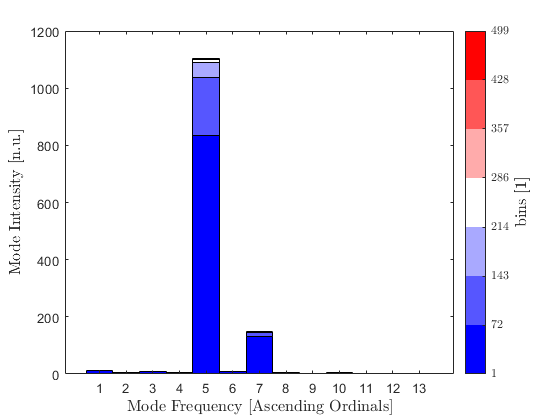

domStruct(dmd, freqs, lambda, Phi, b, tSize);

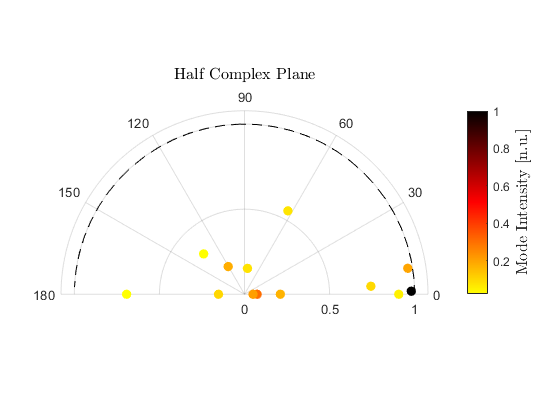

nyqPlot(dmd, norms, freqs, mags, lambda);

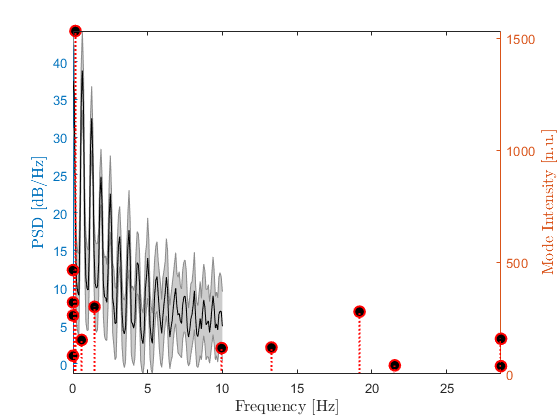

powSpect(dmd, X, freqs, norms, rank);

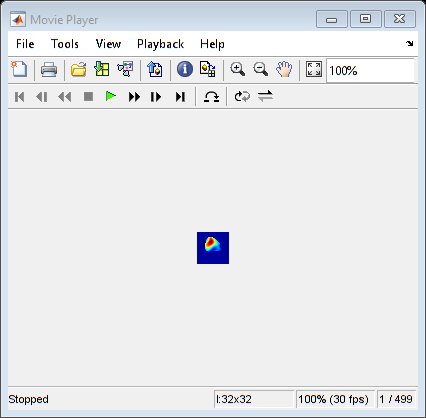


[Xcomps, Xtotal] = reconData(dmd, lambda, omega, Phi, b, tSize, fs, 'cont');

playVideo(reshape(real(Xtotal),32,32,[]));

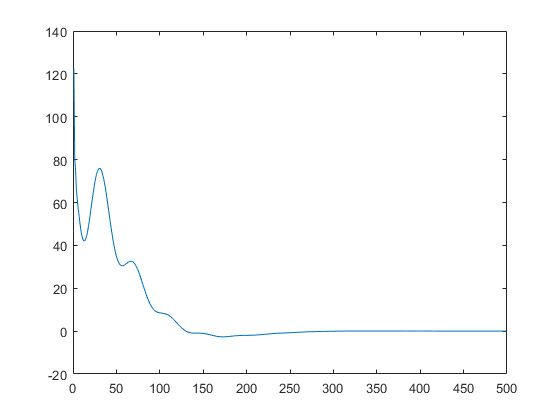


sig = real(reshape(Xtotal,32,32,tSize));
figure; plot(squeeze(sig(heartPix(1),heartPix(2),:)));

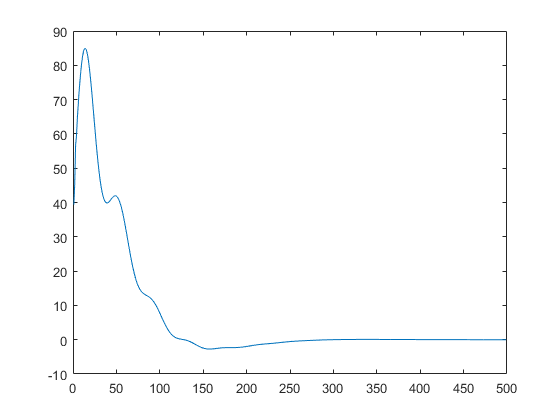

figure; plot(squeeze(sig(lungPix(1),lungPix(2),:)));

% Compressed Multi-Resolution DMD
% Set desired ranges for frequency, norm (or damping factor), and magnitude
nLevels = 5;
freqLims = [1,10];
damLims = [0.9,1];
magLims = [0, 1];

% Calculate heart and lung masks from first singular vectors for ROI-based
% selection of DMD modes
[Umask, ~, ~] = svd(X, 'econ');
eigROI = reshape(Umask(:,2), 32, 32);
absEigROI = abs(eigROI);

noiseMask = stdMap < max(stdMap(:)) * 0.25;

[maxX,maxY] = find(absEigROI == max(absEigROI(:)));

maxVal = eigROI(maxX,maxY);
if maxVal > 0
    heartMask = logical(eigROI > (0.05 * max(eigROI(:))));
    lungMask = logical(eigROI <= (0.05 * min(eigROI(:))));
else
    heartMask = logical(eigROI < (0.05 * min(eigROI(:))));
    lungMask = logical(eigROI >= (0.05 * max(eigROI(:))));
end

heartMask = heartMask & ~noiseMask;
lungMask = lungMask & ~noiseMask;

% Compress data
[cX, cY, ~] = compressData(dmd, X, Y, 128, 2);

% Uncomment for normal multi-resolution  DMD
% cX = X; cY = Y;

tic
[lambda, omega, Phi, b] = mrFit(dmd, cX, cY, rank, nLevels, tSize);

[norms, mags, freqs] = interpModes(dmd, lambda, Phi, b);
[norms, mags, freqs, lambda, omega, Phi, b] = boxSelection(dmd, norms, mags, freqs, ...
                                                                                    lambda, omega, Phi, b, ....
                                                                                    magLims, damLims, freqLims);

% [norms, mags, freqs, lambda, omega, Phi, b] = roiSelection(dmd, 0.9, norms, mags, freqs, lambda, omega, Phi, b, noiseMask, heartMask, lungMask);                                                                               
toc

Elapsed time is 0.236130 seconds.


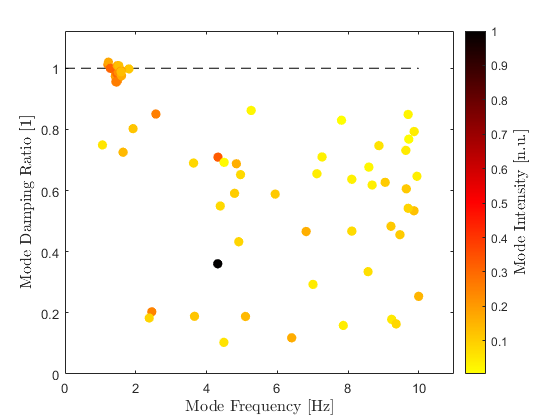


% TODO: add graphic to highlight which ones we're chosen
% among all the modes
damFreq(dmd, norms, mags, freqs);

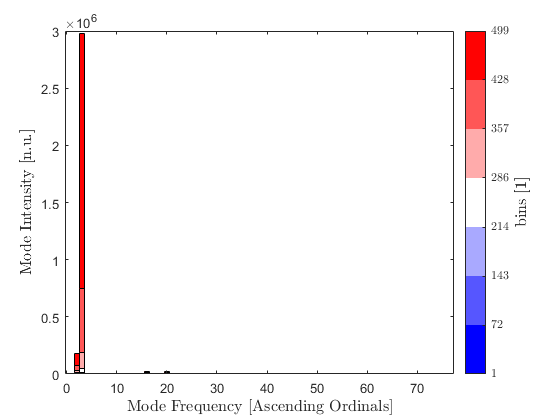

domStruct(dmd, freqs, lambda, Phi, b, tSize);

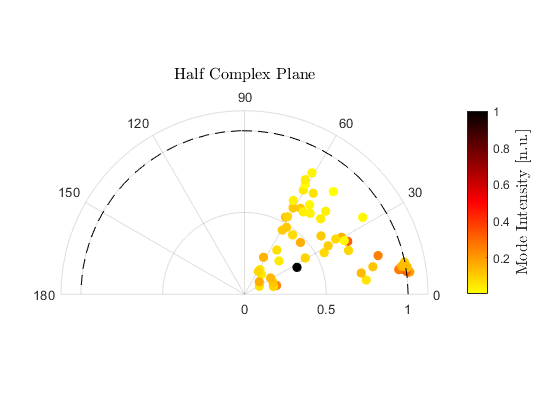

nyqPlot(dmd, norms, freqs, mags, lambda);

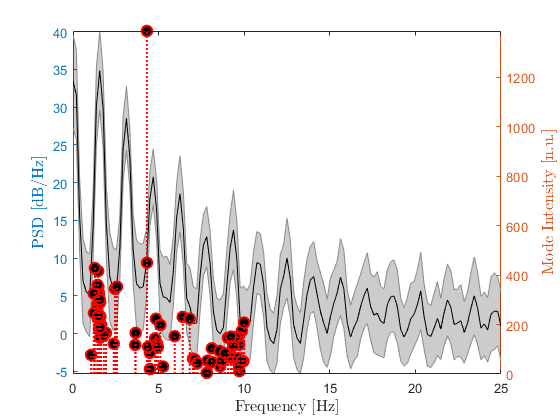


powSpect(dmd, X, freqs, norms, fs);

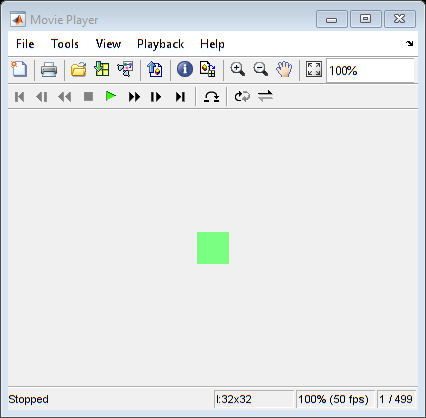


[Xcomps, Xtotal] = reconData(dmd, lambda, omega, Phi, b, tSize, fs, 'cont');

% Check how filtered signal looks like
playVideo(reshape(real(Xtotal),32,32,[]),50);

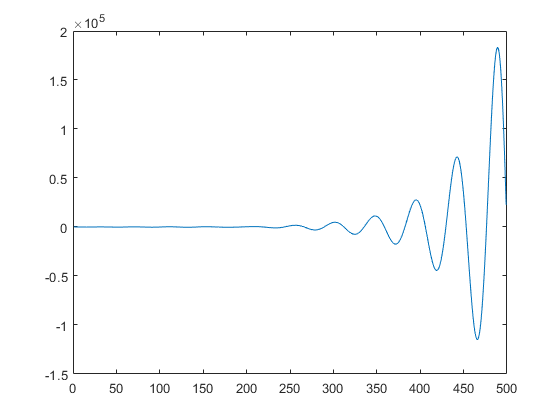


sig = real(reshape(Xtotal,32,32,tSize));
figure; plot(squeeze(sig(heartPix(1),heartPix(2),:)));

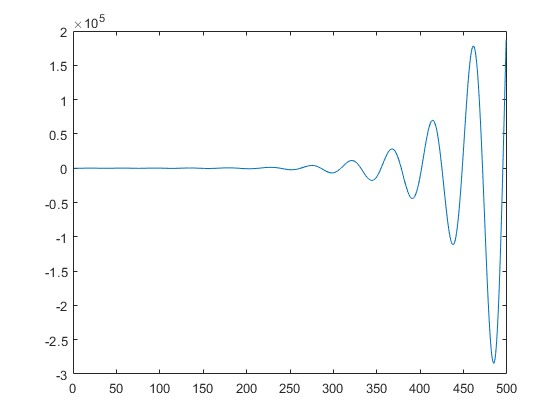

figure; plot(squeeze(sig(lungPix(1),lungPix(2),:)));

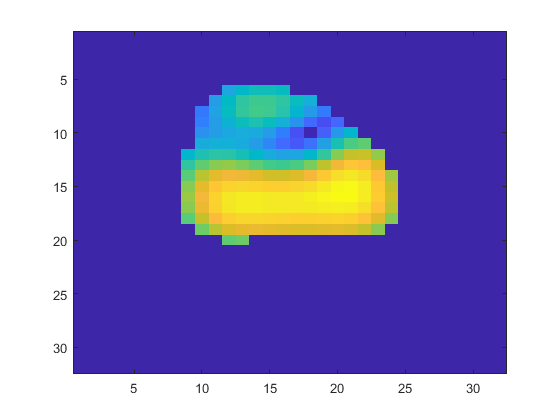

% Calculate standard deviation image of resulting signal
figure; imagesc(std(reshape(real(Xtotal),32,32,[]),[],3))

%TODO: add routine for sample by sample separation